clc;
clear;


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];

joint_path_cls = ['../../../ICRA_2023/joint_process/cls/joints/'];

joint_data_cls = readmatrix([joint_path_cls, 'bag_0.csv']);

joint_path_si = ['../../../ICRA_2023/joint_process/si/joints/'];

joint_data_si = readmatrix([joint_path_si, 'bag_0.csv']);

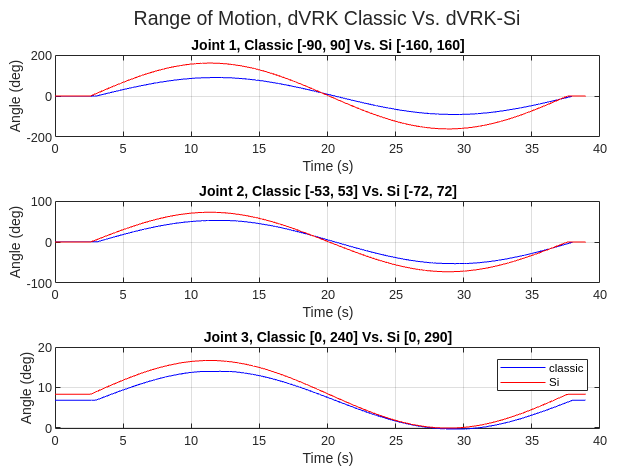



windowSize = 50; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

% fs_force_filt = filter(b,a,fs_force);

figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Range of Motion, dVRK Classic Vs. dVRK-Si'))
% 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,1), 'b')
% % hold on
% % title(sprintf('Fx, RMSE = %.4f', loss_x))
% % plot(0.005 * (1:length(fs_force)), fs_force(:,1), 'r')
% % xlabel('Time/s')
% % ylabel('Force/N')
% % hold off
% % 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,2), 'b')
% % hold on
% % title(sprintf('Fy, RMSE = %.4f', loss_y))
% % plot(0.005 * (1:length(fs_force)), fs_force(:,2), 'r')
% % xlabel('Time/s')
% % ylabel('Force/N')
% % hold off
% % 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,3), 'b')
% % hold on
% % title(sprintf('Fz, RMSE = %.4f', loss_z))
% % plot(0.005 * (1:length(fs_force)), fs_force(:,3), 'r')
% % xlabel('Time/s')
% % ylabel('Force/N')
% % hold off
% % 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,4), 'b')
% % hold on
% % title(sprintf('Taux, RMSE = %.4f', loss_taux))
% % plot(0.005 * (1:length(fs_force)), fs_force(:,4), 'r')
% % xlabel('Time/s')
% % ylabel('Torque/Nm')
% % hold off
% % 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,5), 'b')
% % hold on
% % title(sprintf('Tauy, RMSE = %.4f', loss_tauy))
% % plot(0.005 * (1:length(fs_force)), fs_force(:,5), 'r')
% % xlabel('Time/s')
% % ylabel('Torque/Nm')
% % hold off
% % 
% % nexttile
% % plot(0.005 * (1:length(fs_force)), real_force(:,6), 'b')
% % hold on
% % title(sprintf('Tauz, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% % plot(0.005 * (1:length(fs_force)), fs_force(:,6), 'r')
% % xlabel('Time/s')
% % ylabel('Torque/Nm')
% % legend('measured', 'predicted')
% % hold off
% 
% 
nexttile
plot(joint_data_cls(1:length(joint_data_si)), joint_data_cls(1:length(joint_data_si),2)/3.1415*180, 'b')
hold on
title(sprintf('Joint 1, Classic [-90, 90] Vs. Si [-160, 160]'))
plot(joint_data_si(1:length(joint_data_si)), joint_data_si(1:length(joint_data_si),2)/3.1415*180, 'r')
xlabel('Time (s)')
ylabel('Angle (deg)')
grid on
hold off

nexttile
plot(joint_data_cls(1:length(joint_data_si)), joint_data_cls(1:length(joint_data_si),3)/3.1415*180, 'b')
hold on
title(sprintf('Joint 2, Classic [-53, 53] Vs. Si [-72, 72]'))
plot(joint_data_si(1:length(joint_data_si)), joint_data_si(1:length(joint_data_si),3)/3.1415*180, 'r')
xlabel('Time (s)')
ylabel('Angle (deg)')
grid on
hold off

nexttile
plot(joint_data_cls(1:length(joint_data_si)), joint_data_cls(1:length(joint_data_si),4)/3.1415*180, 'b')
hold on
title(sprintf('Joint 3, Classic [0, 240] Vs. Si [0, 290]'))
plot(joint_data_si(1:length(joint_data_si)), joint_data_si(1:length(joint_data_si),4)/3.1415*180, 'r')
grid on
xlabel('Time (s)')
ylabel('Angle (deg)')
hold off

legend('classic', 'Si')

hold off


% nexttile
% plot(joint_data(27000/4*3:length(fs_force)), real_force(27000/4*3:27000,2), 'b')
% hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
% plot(joint_data(27000/4*3:length(fs_force)), fs_force(27000/4*3:27000,2), 'r')
% xlabel('Time/s')
% ylabel('Force/N')
% hold off
% 
% nexttile
% plot(joint_data(27000/4*3:length(fs_force)), real_force(27000/4*3:27000,3), 'b')
% hold on
% title(sprintf('Fz, RMSE = %.4f', loss_z))
% plot(joint_data(27000/4*3:length(fs_force)), fs_force(27000/4*3:27000,3), 'r')
% xlabel('Time/s')
% ylabel('Force/N')
% 
% xlabel('Time/s')
% ylabel('Torque/Nm')
% legend('measured', 'predicted')
% 
% hold off

% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,4), 'b')
% hold on
% title(sprintf('Taux, RMSE = %.4f', loss_taux))
% plot(joint_data(1:length(fs_force)), fs_force(:,4), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,5), 'b')
% hold on
% title(sprintf('Tauy, RMSE = %.4f', loss_tauy))
% plot(joint_data(1:length(fs_force)), fs_force(:,5), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,6), 'b')
% hold on
% title(sprintf('Tauz, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(joint_data(1:length(fs_force)), fs_force(:,6), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% legend('measured', 'predicted')
% hold off




